# System of Nonlinear Equations

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

In this activity, you'll visualize and solve the following system of equations

2*x**y*−2*y^*2=1

*y^*3=cos(*x*)

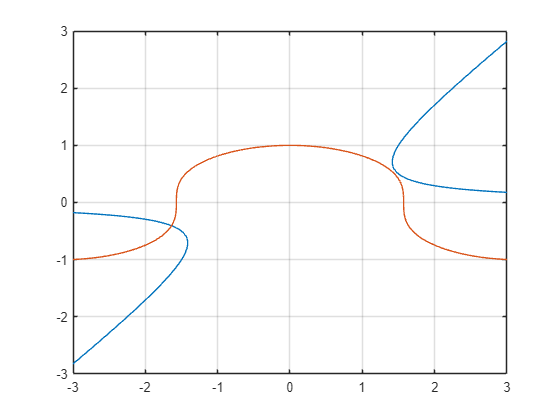

g = @(x, y) 2*x.*y - 2*y.^2 - 1;
h = @(x, y) y.^3 - cos(x);
fimplicit(g, [-3 3])
grid on
hold on
fimplicit(h, [-3 3])
hold off

## Task 2

mySystem = @(w) [   g(w(1),w(2));
                    h(w(1),w(2))];
w0 = [-1.5; -0.5];
wRoot = fsolve(mySystem, w0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


wRoot =    -1.6377
   -0.4059
